clc, clear all, close all

# Load Trained Net

- Load Trained Net to workspace and save it to variable 'TrainNet'

    [netfile,netpath] = uigetfile('.mat','select network');
    TrainNet = load(fullfile(string(netpath)+string(netfile)));

- Load inputsize

    inputSize = TrainNet.trainedNet.Layers(1).InputSize;

- see layer in Trained Net

    NetLayer = TrainNet.trainedNet.Layers;

# Prepare Test Data

**    Get test data**

    test_Data = uigetdir('*.*','select test folder');

**    Create datastore of test data**

    test = imageDatastore(test_Data,'IncludeSubfolders',true,'LabelSource','foldernames');

**    Image dugmentation to test data**

    augTest = augmentedImageDatastore(inputSize,test,'ColorPreprocessing','gray2rgb');

    **See test data**

    
    test_confirmation = countEachLabel(test)

test_confirmation = 2×2 table
    Label     Count
    ______    _____

    Pass       50  
    Reject     50  


#  Let Test!

    tic
    [Pred, scores] = classify(TrainNet.trainedNet,augTest); 
    toc

Elapsed time is 3.897810 seconds.


     Trueclass = Pred(51:end) == test_data.Labels(51:end);

# Analyze

**    Confusion Chart**

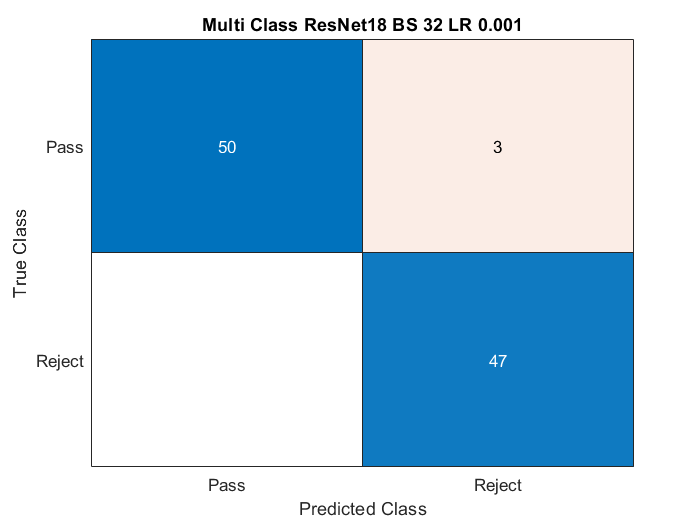

    confusionchart(test.Labels, Pred, "Title",'Multi Class ResNet18 BS 32 LR 0.001')

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

- see what wrong

    Pred == test.Labels;

- show image in the index that are 0, it is the wrong classification image

%     imshow(readimage(test,63))

    **Test accuracy**

    TestAccuracy = nnz(Pred == test.Labels)/length(test.Labels)*100

TestAccuracy = 97

**    ROC**

[X,Y,T,AUC,OPTROCPT,SUBY,SUBYNAMES] = perfcurve(test.Labels, abs(1-scores(1:end/2)), 'Reject');

- AUC

    AUC = AUC*100

AUC = 98.9800

- Plot ROC curve

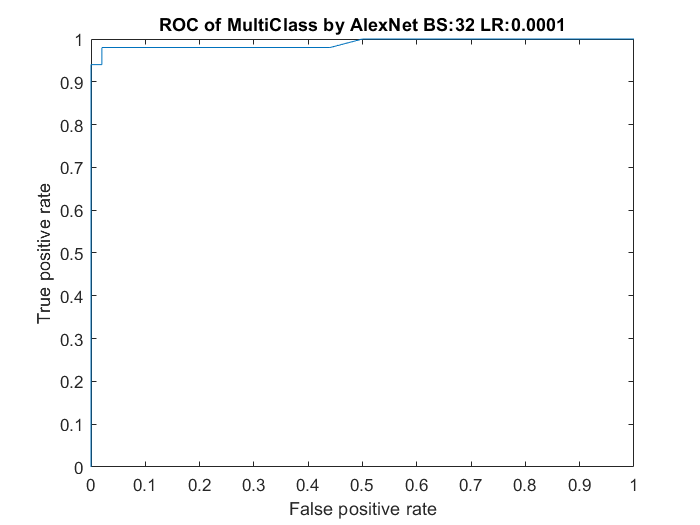

    plot(X,Y)
    xlabel('False positive rate') 
    ylabel('True positive rate')
    title('ROC of MultiClass by AlexNet BS:32 LR:0.0001')

# Test one image

Get image

% [Test1file,Test1path] = uigetfile('*.*','Select Test Picture');
% Test1 = imread(fullfile(string(Test1path)+string(Test1file)));

Image augmentation

% augTest1 = augmentedImageDatastore(inputSize,Test1,'ColorPreprocessing','gray2rgb');

Predict

% [label,scores] = classify(TrainNet.trainedNet,augTest1);

Show

% imshow(Test1) 
% title(string(label(1)));

# Looking in the black box

-  Select Image (Note: can select only on same folder)

%     [Testfile,Testpath] = uigetfile('*.*','Select Test Picture');
%     Test2 = imread(fullfile(string(Testpath)+string(Testfile)));
%     imshow(Test2)

- Augmentation image

%     augTest2 = augmentedImageDatastore(inputSize,Test2,'ColorPreprocessing','gray2rgb');

**See Layers names**

% TrainNet.trainedNet.Layers

**See whole activation**

- Which Activation do you want to see

%     act1 = activations(TrainNet.trainedNet,augTest2,'res2a_branch2a');

- Let see

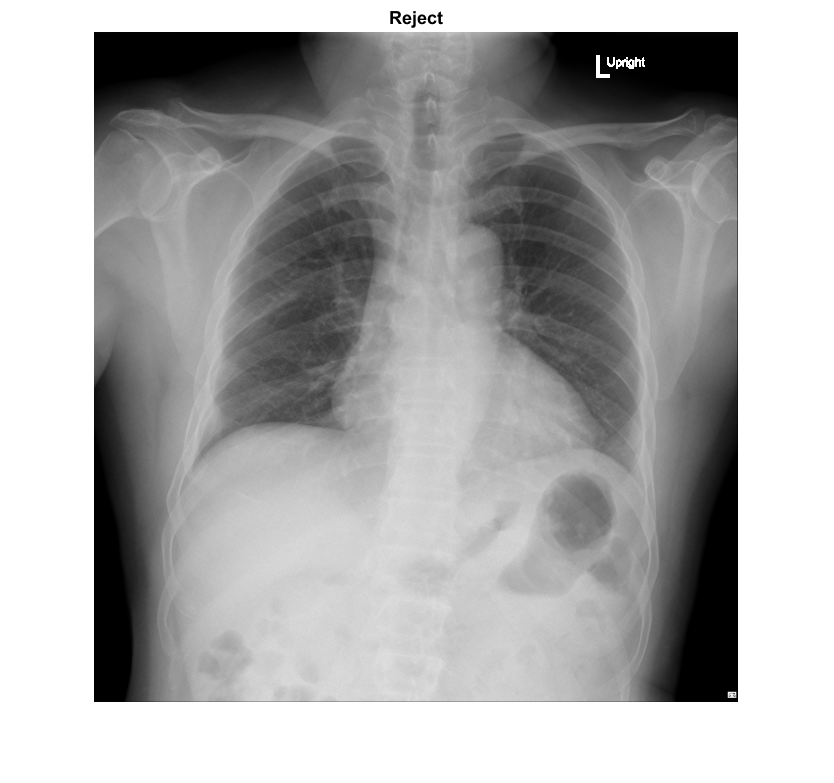

%     montage(mat2gray(act1))

**See specific channal**

- Let see some specific channal

%     showActivationsForChannel(Test2,act1,2)

**See Class Activation Map (CAM)**

-     load net

%     netName = "resnet18"
%     net = TrainNet.trainedNet;

- see inputSize, Classes, layerName

%     inputSize = net.Layers(1).InputSize(1:2);
%     classes = net.Layers(end).Classes;
%     layerName = activationLayerName(netName);

- Display Class Activation Map

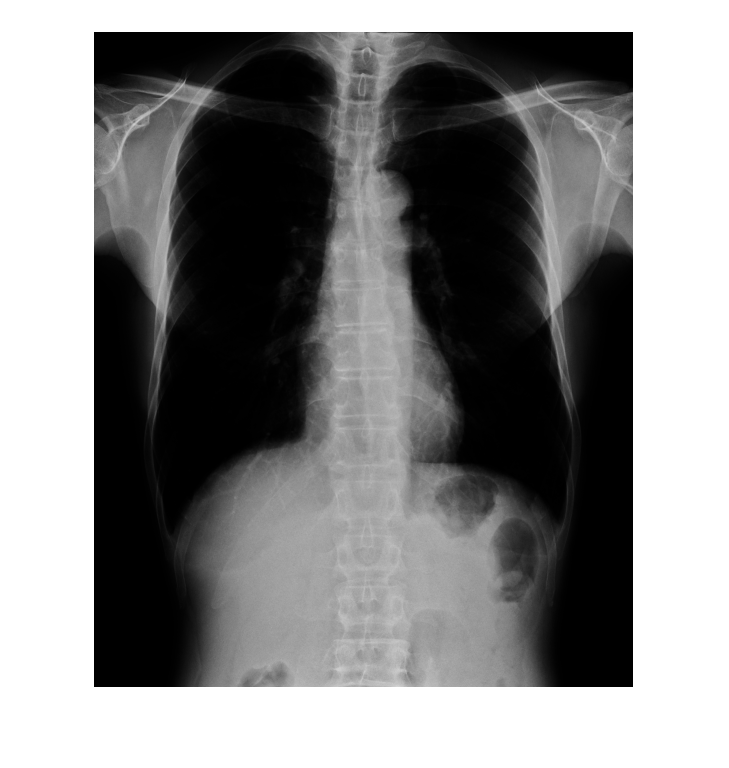

%     im = augTest2;

%     imageActivations = activations(net,im,layerName);
%     scores = squeeze(mean(imageActivations,[1 2]));

%     fcWeights = net.Layers(end-2).Weights;
%     fcBias = net.Layers(end-2).Bias;
%     scores =  fcWeights*scores + fcBias;

ans =   71×1 Layer array with layers:

     1   'data'                  Image Input              224×224×3 images with 'zscore' normalization
     2   'conv1'                 Convolution              64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'              Batch Normalization      Batch normalization with 64 channels
     4   'conv1_relu'            ReLU                     ReLU
     5   'pool1'                 Max Pooling              3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'        Convolution              64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'bn2a_branch2a'         Batch Normalization      Batch normalization with 64 channels
     8   'res2a_branch2a_relu'   ReLU                     ReLU
     9   'res2a_branch2b'        Convolution              64 3×3×64 convolutions with stride [1  1

%     [~,classIds] = maxk(scores,3);
%     weightVector = shiftdim(fcWeights(classIds(1),:),-1);
%     classActivationMap = sum(imageActivations.*weightVector,3);

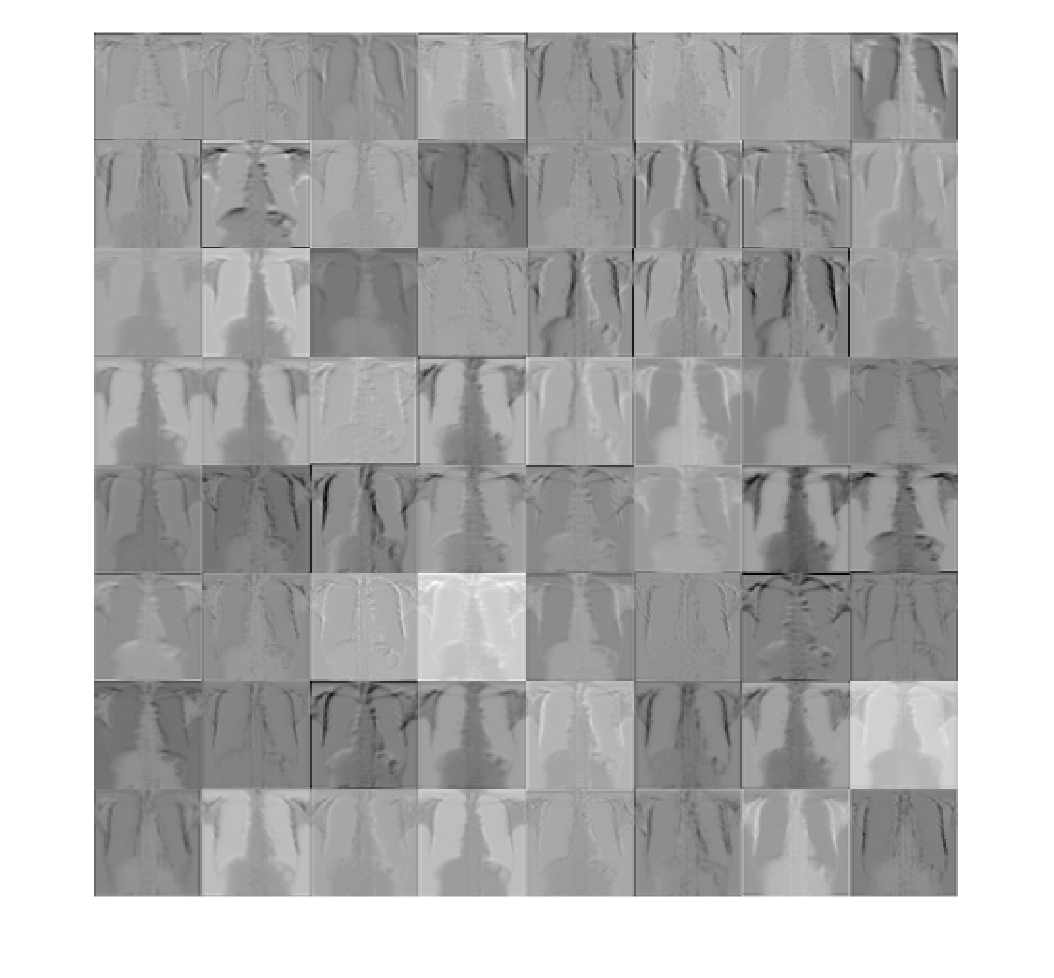

%     scores = exp(scores)/sum(exp(scores));     
%     maxScores = scores(classIds);
%     labels = classes(classIds);

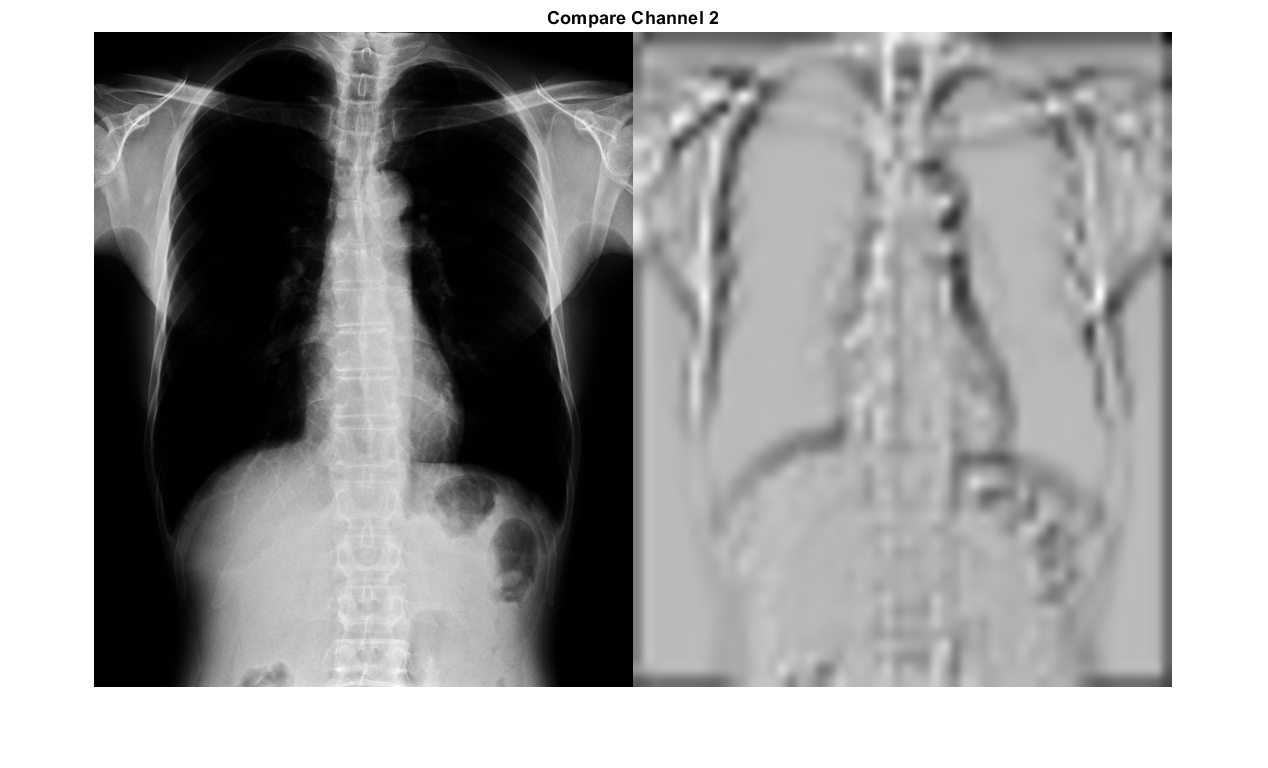

%     subplot(1,2,1)
%     imshow(Test2)
%     subplot(1,2,2)
%     CAMshow(Test2,classActivationMap)

%     title(string(labels) + ": " + string(maxScores*100)+'%');

# Function

- Activations For Channel

%     function showActivationsForChannel(origImage,ac,ch)
%         imageSize = size(origImage);
%         imageSize = imageSize([1 2]);

netName = "resnet18"

%         act_ch = ac(:,:,ch);
%         act_ch = imresize(mat2gray(act_ch),imageSize);
%         imshowpair(origImage,act_ch,'montage')
%         title(['Compare Channel ',num2str(ch)])
%     end

- CAM

%     function CAMshow(im,CAM)
%         imSize = size(im);
%         CAM = imresize(CAM,imSize(1:2));
%         CAM = normalizeImage(CAM);
%         CAM(CAM<0.2) = 0;
%         cmap = jet(255).*linspace(0,1,255)';
%         CAM = ind2rgb(uint8(CAM*255),cmap)*255;
%         combinedImage = double(im)/2 + CAM;
%         combinedImage = normalizeImage(combinedImage)*255;
%         imshow(uint8(combinedImage));
%     end
%     

%     function N = normalizeImage(I)
%         minimum = min(I(:));
%         maximum = max(I(:));
%         N = (I-minimum)/(maximum-minimum);
%     end
%     

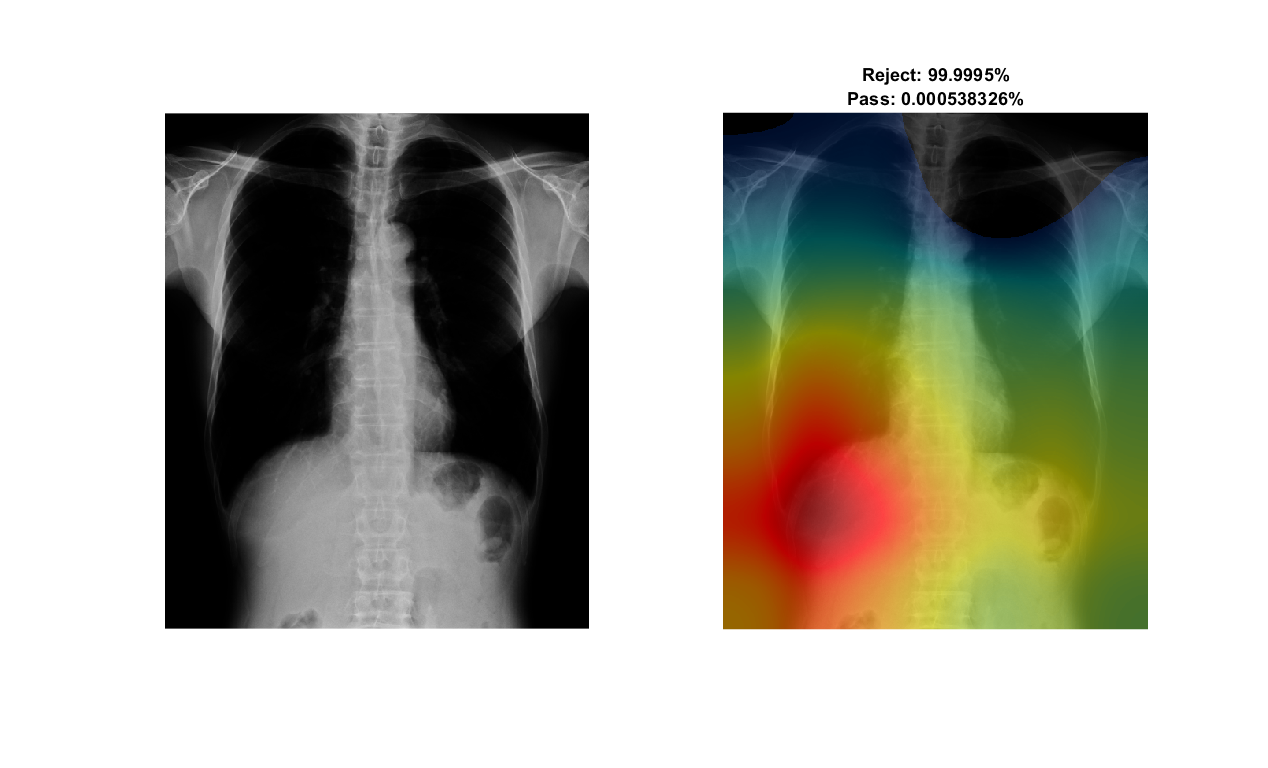

%     function layerName = activationLayerName(netName)
%     
%         if netName == "alexnet"

%             layerName = 'relu7';
%         elseif netName == "googlenet"
%             layerName = 'inception_5b-output';
%         elseif netName == "resnet18"
%             layerName = 'res5b_relu';
%         elseif netName == "mobilenetv2"
%             layerName = 'out_relu';
%         end
%     
%     end